1번문제

function y = f1(x)
y = 0.3.*x -sin(2.*x);
end

x1 = fminbnd(@f1,0,4);
x1 %최소일때 x값

x1 = 0.7101

z1 = f1(x1) %최소

z1 = -0.7757

y1 = fzero(@f1,[0.1 4]); %0일때 근이 0이기 때문에 0을 제외
y1

y1 = 1.3606


x = linspace(0,4,1000);
y = f1(x);
min(y)

ans = -0.7756

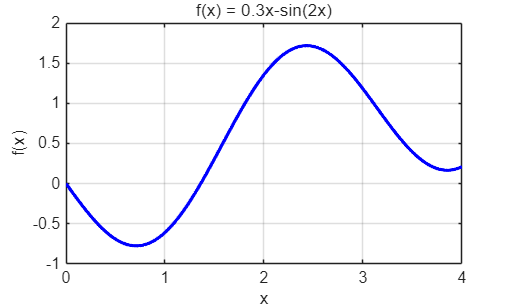

figure;
plot(x,y, 'b-', 'LineWidth', 2); hold on;
grid on
xlabel('x');
ylabel('f(x)');
title('f(x) = 0.3x-sin(2x)')

%그래프를 통해 최소 확인

2번문제

function y2 = f2(t)
h2 = 100;
v = 50;
g = 9.81;
y2 = v.*t - (g.*t.^2)./2 -h2;
end
t1 = fzero(@f2, 2)

t1 = 2.7324

t2 = fzero(@f2, 8)

t2 = 7.4612


%두개의 t가 나오는데, t1은 물체가 올라갈 때, h = 100을 지나는 시간 t이고
%t2는 물체가 최고점을 찍고 다시 내려올 때, h = 100을 지나는 t이다.

3번문제

function A3 = cone(r)
global V
A3 = pi.*r.*(sqrt(r.^2 + 9.*V.^2./((pi.^2).*(r.^4)))); %(a)답
end

%(b)
global V
V =10;

%(c)
r3 = fminbnd(@cone, 0.01, 10) %A를 최소로 만드는 r

r3 = 1.8901

h3 = 3.*V/(pi.*(r3.^2)) %이때의 높이 h

h3 = 2.6730

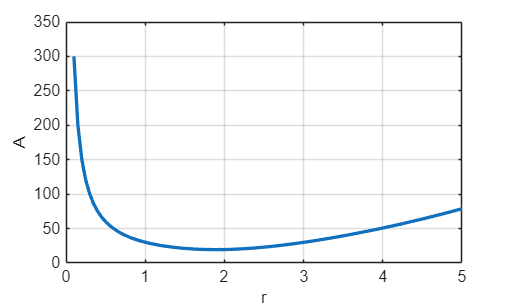


r = linspace(0.1,5,100);
A = cone(r);

figure;
plot(r,A,'LineWidth',2);hold on;

A_min = cone(r3);
plot(r3, A_min);

grid on
xlabel('r')
ylabel('A')


A_limit = 1.1 * A_min;

idx = find(A <= A_limit);
r_range = max(r(idx)) %R 벗어날 수 있는 최대

r_range = 2.3273

4번문제

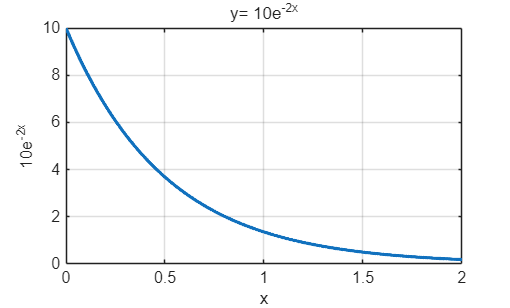

ex4 = @(x) 10*exp(-2*x);
x4 = linspace(0,2,1000);
y4 = ex4(x4);

figure
plot(x4, y4, 'Linewidth', 2);

grid on
xlabel('x')
ylabel('10e^{-2x}')
title('y= 10e^{-2x}')

5번문제

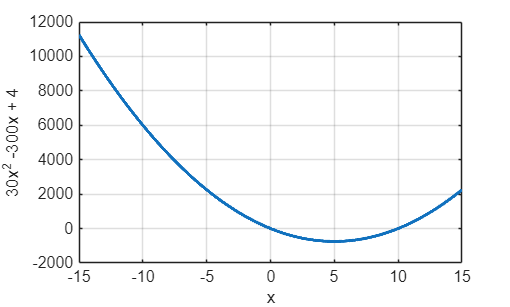

ex5 = @(x) 30.*x.^2 -300.*x + 4;

x5 = linspace(-15,15,3000);
y5 = ex5(x5);

figure
plot(x5,y5,'LineWidth',2); 
grid on
xlabel('x')
ylabel('30x^2 -300x + 4')


disp("최소값")

최소값


fminbnd(ex5,-15,15) %최소값

ans = 5

6번문제

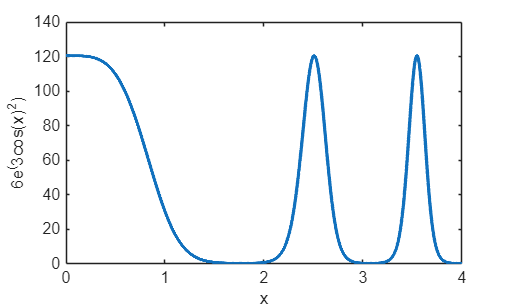

h6 = @(x) 6.*exp(x);
g6 = @(x) 3.*cos(x);
f6 = @(x) x.^2;
k6 = @(x) h6(g6(f6(x)));

x = linspace(0,4,4000);
y = k6(x);
plot(x,y,"LineWidth",2);
xlabel('x')
ylabel('6e^(3cos(x)^2)')